%%%% List of Audio Files From Current Folder  %%%%
x = 35; charpref = "000010"; charsuff = ".wav"; audioFiles = strings(1, x); chSelect = 1;
for xa = 1:x
    if xa < 10
        charf = "0" + int2str(xa); % Ensure leading zero
    else
        charf = int2str(xa);
    end 
    charfile = charpref + charf + charsuff;
    audioFiles(xa) = charfile;
end

disp(audioFiles);

    "00001001.wav"    "00001002.wav"    "00001003.wav"    "00001004.wav"    "00001005.wav"    "00001006.wav"    "00001007.wav"    "00001008.wav"    "00001009.wav"    "00001010.wav"    "00001011.wav"    "00001012.wav"    "00001013.wav"    "00001014.wav"    "00001015.wav"    "00001016.wav"    "00001017.wav"    "00001018.wav"    "00001019.wav"    "00001020.wav"    "00001021.wav"    "00001022.wav"    "00001023.wav"    "00001024.wav"    "00001025.wav"    "00001026.wav"    "00001027.wav"    "00001028.wav"    "00001029.wav"    "00001030.wav"    "00001031.wav"    "00001032.wav"    "00001033.wav"    "00001034.wav"    "00001035.wav"



numFiles = length(audioFiles);

%%%% Feature Storage Initialization  %%%%
allFeatures = [];
labels = [];

%%%% Loop Through Audio Files to Generate Features from Their First Channel  %%%%
%%%% Chosen channel is dictated by "chSelect" at top of script.              %%%%

for i = 1:numFiles
    fileName = audioFiles(i);

    % Extract Features (Using Previously Defined Functions)
    timeFreqFeatures = generateAudioFeatures(fileName, chSelect); % Time & Frequency Features
    fftFeatures = generateFFTFeatures(fileName, chSelect, 1024); % FFT Features

    % Combine Features
    featureVector = [table2array(timeFreqFeatures), table2array(fftFeatures)];

    % Store Data
    allFeatures = [allFeatures; featureVector];
    labels = [labels; fileName]; % Store Label (File Name)
end

%%%% Convert Selected Features to a Table  %%%%
featureNames = [timeFreqFeatures.Properties.VariableNames, fftFeatures.Properties.VariableNames];
featureTable = array2table(allFeatures, 'VariableNames', featureNames);
featureTable.Label = labels; % Add Labels

%%%% View Selection  %%%%
disp(featureTable);

      RMS       ZeroCrossRate    SpectralCentroid     MFCC1      MFCC2      MFCC3       MFCC4         MFCC5        MFCC6        MFCC7         MFCC8         MFCC9        MFCC10        MFCC11        MFCC12       MFCC13        MFCC14      MaxFreqMag    MeanFreqMag    MedianFreqMag    DominantFreq        Label     
    ________    _____________    ________________    _______    _______    _______    __________    _________    _________    __________    



%%%% Convert Features to a Numeric Array  %%%%
featureMatrix = table2array(featureTable(:, 1:end-1));

%%%% PCA Calculation (2 Components)  %%%%
[coeff, score, ~, ~, explained] = pca(featureMatrix);

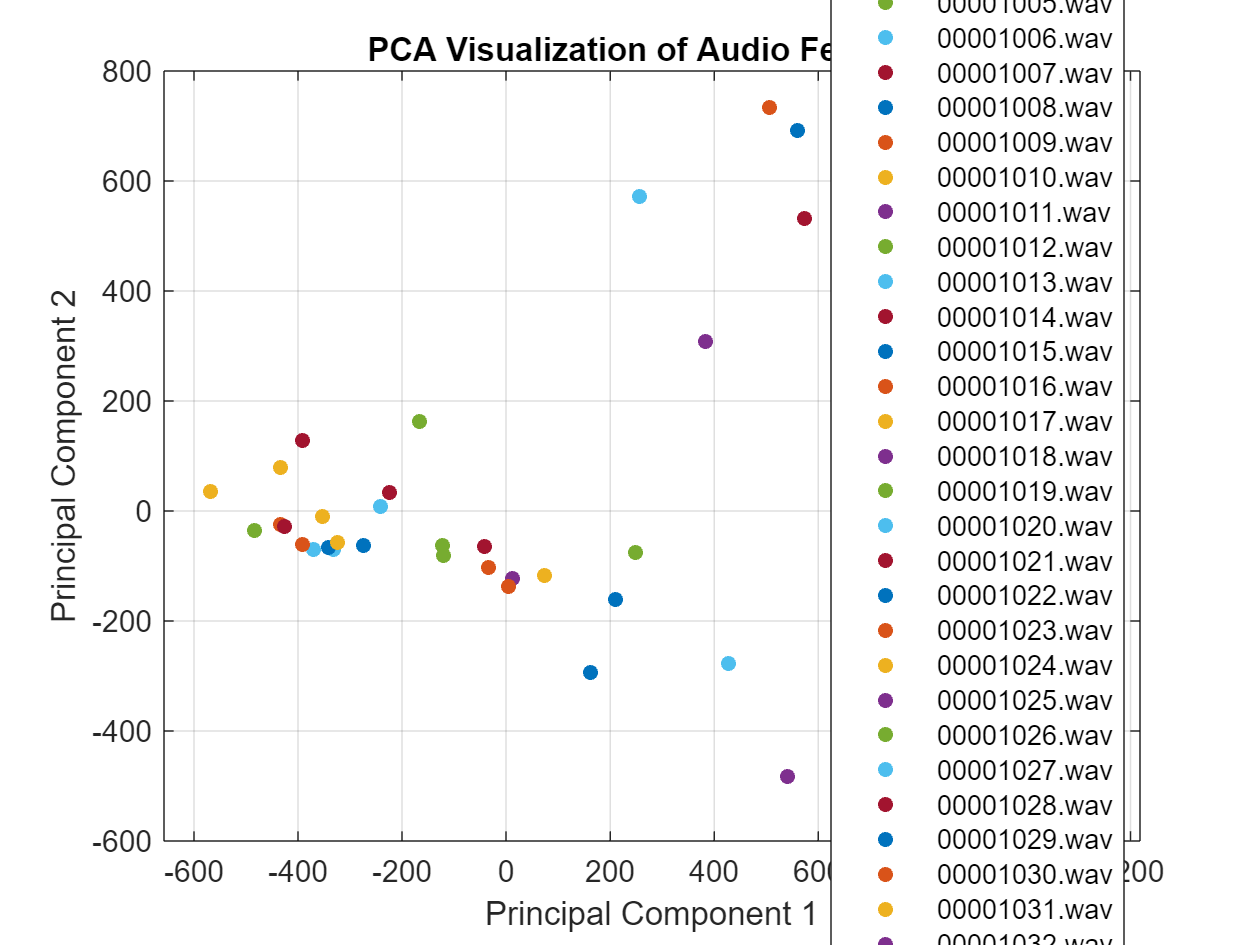


%%%% Scatter Plot of First 2 PCA Components  %%%%
figure;
gscatter(score(:,1), score(:,2), featureTable.Label);
xlabel("Principal Component 1");
ylabel("Principal Component 2");
title("PCA Visualization of Audio Features");
grid on;

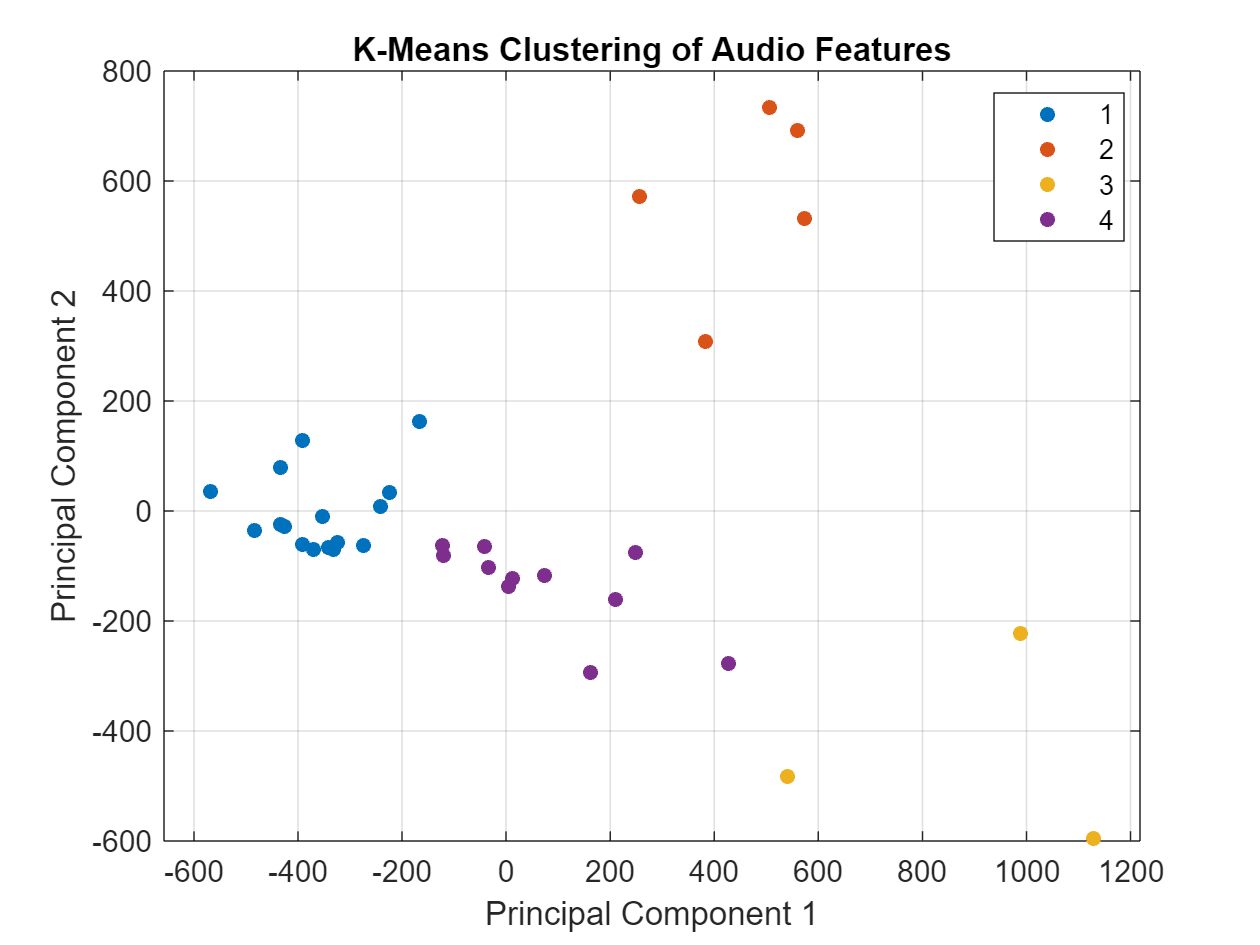



%%%% Number of Clusters to Categorize (I chose 4)  %%%%
numClusters = 4;
[idx, C] = kmeans(featureMatrix, numClusters, 'Replicates', 5);

%%%% Plot Chosen Clusters  %%%%
figure;
gscatter(score(:,1), score(:,2), idx);
xlabel("Principal Component 1");
ylabel("Principal Component 2");
title("K-Means Clustering of Audio Features");
grid on;